## **Taller 13 - 15: **Péndulo simple con fuerza tangencial.

**Estudiante: **Daniel Palacio Gónzalez.

**ID: **1000000247116

**CC: **1006982908

**    INTRODUCCIÓN**

En este taller se pretende estudiar el comportamiento de un péndulo simple con fuerza tangencial a través de un sistema de ecuaciones diferenciales. De igual manera, se busca comprender la forma en la que las variables de estado influyen en el sistema a través de la repetición del estudio con diferentes valores de estas. Dicho análisis se realizará haciendo uso de la herramienta virtual MATLAB, especialmente con el uso de la función ode45 de odeFunction.

    **   MODELO A ANALIZAR**

Se entraga el siguiente sistema de ecuaciones diferenciales:

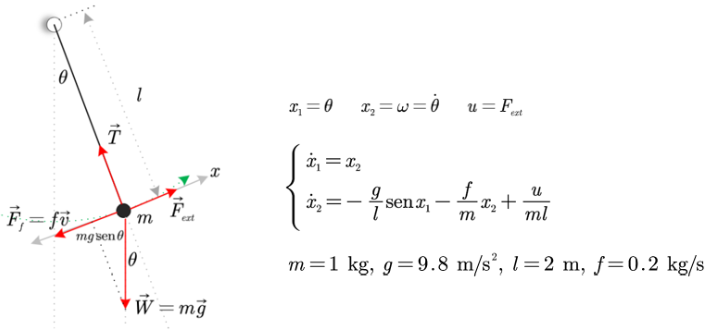

Donde:

- $\theta$: posición angular [rad].

- $\omega$: velocidad angular [rad/s].

- u: Fuerza tangencial [N].

- m: masa [kg].

- l: longitud del cable [m].

- g: Aceleración gravitacional [$\frac{m}{s^2 }$].

- f: coeficiente de fricción viscosa [kg/s].

Además, se asume que el hilo del péndulo es rígido y tiene una masa despreciable.

**    PUNTO 1**

Resolver numéricamente la ecuación diferencial no lineal y graficar las soluciones temporales con una entrada u = 1. 

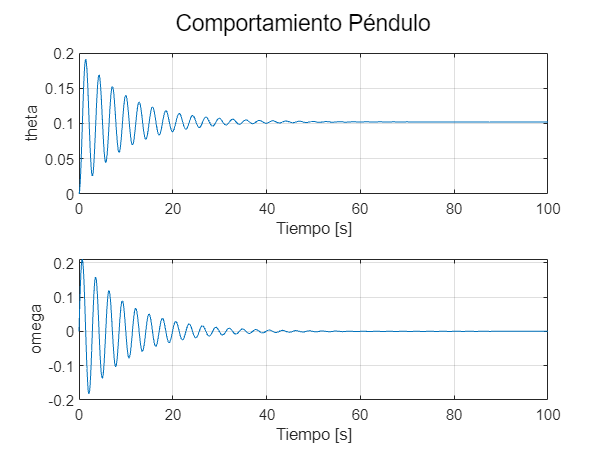

syms x1(t) x2(t)

%DEFINIMOS VARIABLES DE ESTADO
m=1; %masa
g=9.8; %gravedad
l=2; %longitud [m]
f=0.2; %factor de fricción
u=1; %Fuerza tangencial

%PLANTEAMOS ECUACIONES DIFF
f1=x2;
f2=-(g/l)*sin(x1)-(f/m)*x2+u/(m*l);

%EMPLEAMOS ODEFUNCTION
func=odeFunction([f1 f2], [x1 x2]);
tspan=0:0.1:100;
ci=[0 0];

%RESOLVEMOS EC PARA u=1
[t,sln]=ode45(func,tspan,ci);
theta=sln(:,1);
omega=sln(:,2);

%GRAFICAMOS POSICIÓN Y VELOCIDAD PARA u=1
subplot(2,1,1);
plot(t,theta)
xlabel('Tiempo [s]')
ylabel('theta')
grid on

subplot(2,1,2);
plot(t,omega)
xlabel('Tiempo [s]')
ylabel('omega')
grid on

sgtitle('Comportamiento Péndulo')

Como se observa en las gráficas de posición y velocidad angular, se presenta un movimiento oscilatorio simple donde, con el paso del tiempo, la masa tiende a la quietud. Esto se explica gracias a variables como la fricción que se encargan de robarle energía al sistema.

¿Para qué valor máximo de la entrada el sistema rotará indefinidamente?

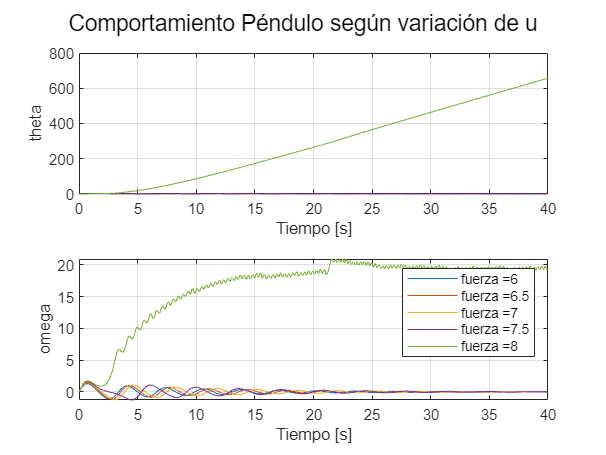

clf
syms x1(t) x2(t)

%DEFINIMOS VARIABLES DE ESTADO
m=1; %masa
g=9.8; %gravedad
l=2; %longitud [m]
f=0.2; %factor de fricción

u=6:0.5:8; %Fuerza tangencial
L=length(u);

tspan=0:0.01:40;
names=cell(1,L);

for i=1:L
    f1=x2;
    f2=-(g/l)*sin(x1)-(f/m)*x2+u(i)/(m*l);

    %EMPLEAMOS ODEFUNCTION
    func=odeFunction([f1 f2], [x1 x2]);
    ci=[0 0];
    [t,sln]=ode45(func,tspan,ci);
    
    theta=sln(:,1);
    omega=sln(:,2);

    names{i}=['fuerza =', num2str(u(i))];

    subplot(2,1,1);
    plot(t,theta)
    xlabel('Tiempo [s]')
    ylabel('theta')
    grid on
    hold on

    subplot(2,1,2);
    plot(t,omega)
    xlabel('Tiempo [s]')
    ylabel('omega')
    grid on
    hold on

    sgtitle('Comportamiento Péndulo según variación de u')

end
legend(names)

Como se describe en el sistema, al aumentar la fuerza tangencial aplicada al péndulo, a este le tomará mayor tiempo estabilizarse. Sin embargo, dadas las variables de estado del sistema, para una fuerza payor a proximadamente 7.5 N el sistema no llegará nunca al reposo. Lo anterior sucede principalmente debido al bajo coeficiente de fricción del sistema el cual no es capaz de detener el péndulo al someterlo a una fuerza superior a la especificada anteriormente.

**    PUNTO 2**

Trazar la curva de linealidad, es decir, el valor en el que se estabiliza el péndulo en función del valor de la entrada. El rango de entradas no debe superar el valor máximo calculado anteriormente.

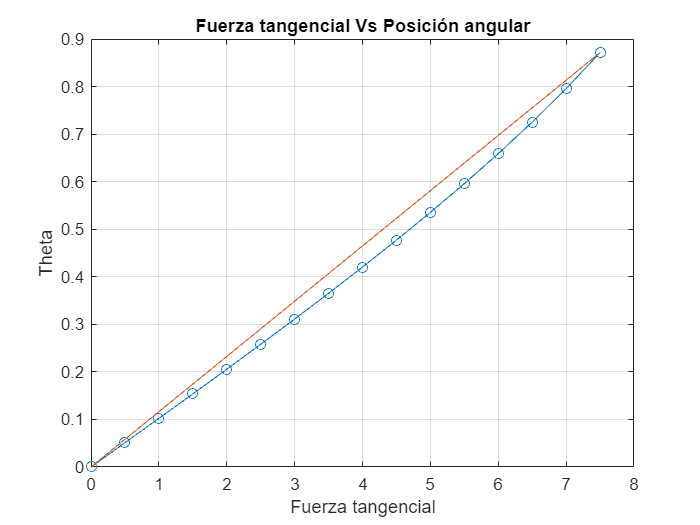

syms x1(t) x2(t)

%DEFINIMOS VARIABLES DE ESTADO
m=1; %masa
g=9.8; %gravedad
l=2; %longitud [m]
f=0.2; %factor de fricción
uv=0:0.5:7.5; %vector de fuerza tangencial con salto de 0.5
L=length(uv); %tamaño de vector uv
theta=zeros(1,L); %Vector teta vacío del tamaño de uv
tspan=0:0.1:100;
f1=x2;
ci=[0 0];

%CREAMOS CICLO DE SOLUCIÓN DE ECUACION DIFF
for i=1:L
    u=uv(i);
    f2=-(g/l)*sin(x1)-(f/m)*x2+u/(m*l);
    func=odeFunction([f1 f2], [x1 x2]);
    [~,sln]=ode45(func,tspan,ci);
    theta(i)=sln(end,1);
end

%PLOTEAMOS GRÁFICO DE RESULTADOS VS RECTA TEÓRICA
figure;
plot(uv,theta,'o-',[0 uv(end)],[0 theta(end)])
title('Fuerza tangencial Vs Posición angular')
xlabel('Fuerza tangencial')
ylabel('Theta')
grid on

Como se observa en la gráfica anterior, el comportamiento de la estabilización del sistema en función de la fuerza tangencial no presenta una relación lineal. Lo anterior sucede ya que, a pesar de que en sistemas ideales el comportamiento del movimiento oscilatorio simple presenta un modelo matemático lineal, en condiciones reales el modelo contempla variables como el factor de fricción que afecta de forma no lineal el comportamiento del cuerpo al oscilar.

**    PUNTO 3**

Dibujar el retrato de fase para un cambio en la condición inicial de la velocidad angular entre 3 y 6 rad/s con incrementos de 0.5 rad/s. Interpretar el resultado. ¿Para qué valor de la frecuencia angular inicial el péndulo da una vuelta? ¿Para qué valor da tres vueltas? Observar los puntos de equilibrio.

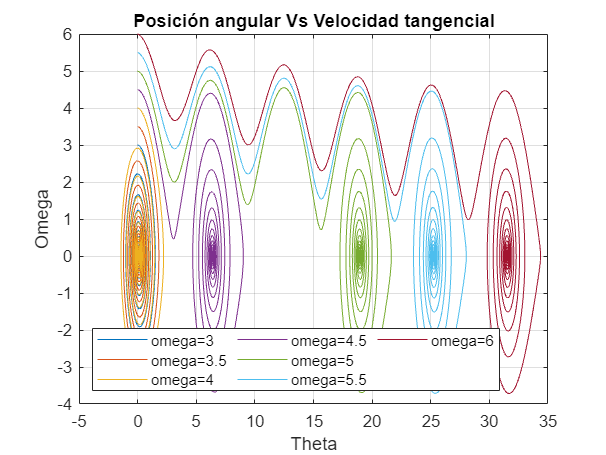

syms x1(t) x2(t)

%DEFINIMOS VARIABLES DE ESTADO
m=1; %masa
g=9.8; %gravedad
l=2; %longitud [m]
f=0.2; %factor de fricción
u=1; %Fuerza tangencial

%PLANTEAMOS ECUACIONES DIFF
f1=x2;
f2=-(g/l)*sin(x1)-(f/m)*x2+u/(m*l);

%EMPLEAMOS ODEFUNCTION
func=odeFunction([f1 f2], [x1 x2]);
tspan=0:0.01:100;
omegav=3:0.5:6; %Vector omega con salto 0.5

%CREAMOS CICLO CON SLN Y GRÁFICA DE LA EC PARA CADDA OMEGA
figure;
for i=1:length(omegav)
    ci = [0 omegav(i)]; 
    [~,sol] = ode45(func,tspan,ci);
    theta = sol(:,1);
    omega = sol(:,2);
    plot(theta,omega)
    title('Posición angular Vs Velocidad tangencial')
    xlabel('Theta')
    ylabel('Omega')
    hold on
    grid on
end
lgnd=legend({'omega=3','omega=3.5','omega=4','omega=4.5','omega=5','omega=5.5','omega=6'},'Location','southwest');
lgnd.NumColumns = 3;

Para este punto, en la gráfica se observa un comportamiento relativamente parecido a una función sinusoidal donde la pesencia de dos picos sucesivos representa una revolución en el sistema. Asimismo, la forma de espiral envolvente representa el punto en el  cuál el péndulo deja de girar y empieza a oscilar para detenerse. Por tanto, se observa que, para un valor de velocidad  angular inicial de 4.5 rad/s, el sistema da una vuelta. Asimismo, para una velocidad angular inicial de 5.0 rad/s, el sistema da 3 revoluciones.

**    PUNTO 4**

Dibujar el retrato de fase para un cambio en la condición inicial de la posición angular entre -6 y 6 rad con incrementos de 0.5 rad. Interpretar el resultado. Observar los tres únicos puntos de equilibrio.

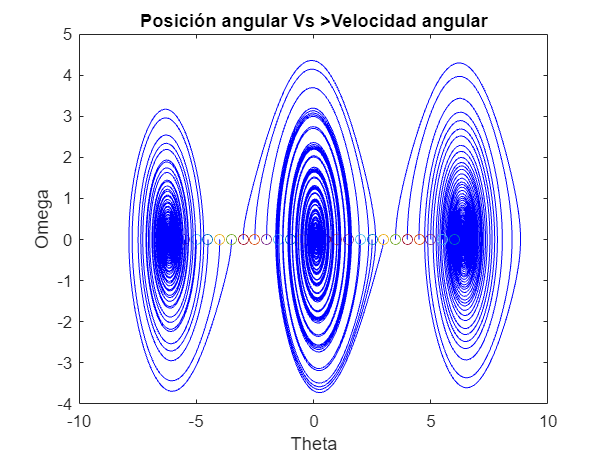

syms x1(t) x2(t)

%DEFINIMOS VARIABLES DE ESTADO
m=1; %masa
g=9.8; %gravedad
l=2; %longitud [m]
f=0.2; %factor de fricción
u=1; %Fuerza tangencial

%PLANTEAMOS ECUACIONES DIFF
f1=x2;
f2=-(g/l)*sin(x1)-(f/m)*x2+u/(m*l);

%EMPLEAMOS ODEFUNCTION
func=odeFunction([f1 f2], [x1 x2]);
tspan=0:0.01:100;
thetav=-6:0.5:6; %Vector theta con salto 0.5

%CREAMOS CICLO CON SLN Y GRÁFICA DE LA EC PARA CADA THETA
figure;
for i=1:length(thetav)
    ci = [thetav(i) 0]; 
    [~,sol] = ode45(func,tspan,ci);
    theta = sol(:,1);
    omega = sol(:,2);
    plot(theta,omega,'b', ci(1), ci(2), 'o')
    title('Posición angular Vs Velocidad angular')
    xlabel('Theta')
    ylabel('Omega')
    hold on
    grid on
end

La gráfica mostrada anteriormente presenta formas de espirales envolventes que convergen en los puntos correspondientes a $-2\pi$,0 y $2\pi$. Estos puntos significan que el sistema se estabiliza sin dar una revolución completa (para el valor de 0 en theta) y, además, se estabiliza tras dar una revoliución completa en (para valores de $-2\pi$ y $2\pi$).

**    PUNTO 5**

Explicar el efecto del cambio de la longitud del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

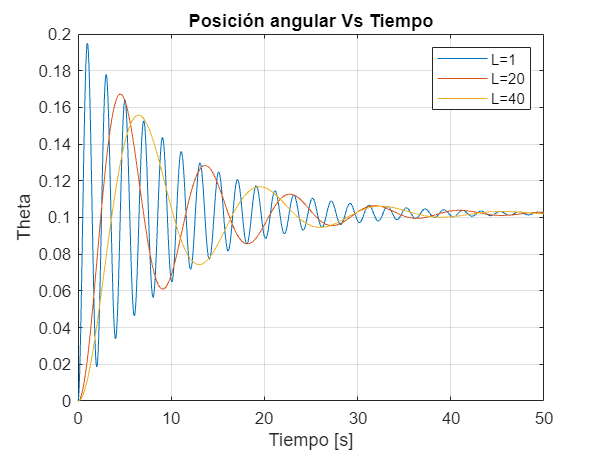

syms x1(t) x2(t)

%DEFINIMOS VARIABLES DE ESTADO
m=1; %masa
g=9.8; %gravedad
lv=[1 20 40]; %longitud [m]
f=0.2; %factor de fricción
u=1; %Fuerza tangencial

tspan=0:0.01:50;

%CREAMOS CICLO CON SLN Y GRÁFICA DE LA EC PARA CADA L
figure;
for i=1:length(lv)
    l=lv(i);
    f1=x2;
    f2=-(g/l)*sin(x1)-(f/m)*x2+u/(m*l);
    ci = [0 0];
    func=odeFunction([f1 f2], [x1 x2]);
    [~,sol] = ode45(func,tspan,ci);
    theta = sol(:,1);
    omega = sol(:,2);
    plot(tspan,theta)
    title('Posición angular Vs Tiempo')
    xlabel('Tiempo [s]')
    ylabel('Theta')
    hold on
    grid on
end
legend('L=1','L=20','L=40')

De acuerdo con la fórmula de periodo oscilatorio de un péndulo simple $T=2\pi \sqrt{\frac{L}{g}}$, la longitud afecta de forma directamente proporcional el periodo de oscilación de un sistema; es decir, si se aumenta la longitud del hilo que sostiene la masa que oscila, aumentará también el periodo de oscilación del sistema. es por tanto que la gráfica anterior presenta una mayor distancia entre picos y valles a medida que se aumenta la magnitud de L.

**    PUNTO 6**

Explicar el efecto del cambio de la masa del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

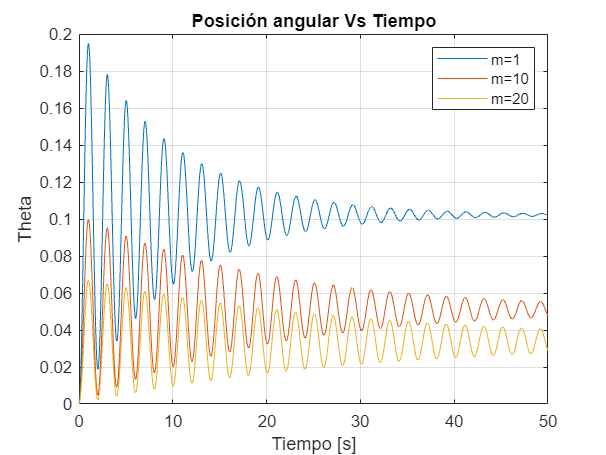

syms x1(t) x2(t)

%DEFINIMOS VARIABLES DE ESTADO
mv=[1 2 3]; %masa
g=9.8; %gravedad
l=1; %longitud [m]
f=0.2; %factor de fricción
u=1; %Fuerza tangencial

tspan=0:0.01:50;

%CREAMOS CICLO CON SLN Y GRÁFICA DE LA EC PARA CADA m
figure;
for i=1:length(mv)
    m=mv(i);
    f1=x2;
    f2=-(g/l)*sin(x1)-(f/m)*x2+u/(m*l);
    ci = [0 0];
    func=odeFunction([f1 f2], [x1 x2]);
    [~,sol] = ode45(func,tspan,ci);
    theta = sol(:,1);
    omega = sol(:,2);
    plot(tspan,theta)
    title('Posición angular Vs Tiempo')
    xlabel('Tiempo [s]')
    ylabel('Theta')
    hold on
    grid on
end
legend('m=1','m=10','m=20')

Otra variable de estado que influye en nuestro modelo matemático es la masa del péndulo que oscila. Este valor es importante dado que define no solo el peso (a mayor peso, mayor resistencia al movimiento), sino que define también la magnitud de energía almacenada en el sistema. Por tanto, es posible observar en la anterior gráfica que, si bien a mayor masa se tienen picos más bajos (es decir que el péndulo no alcanza angulos grandes con respecto a la vertical al oscilar), también se observa que la amplitud entre picos aumenta a mayor masa, con lo cual se comprueba un aumento en la magnitud de la energía almacenada en el sistema.

**    PUNTO 7**

Explicar el efecto del cambio de la fricción viscosa del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

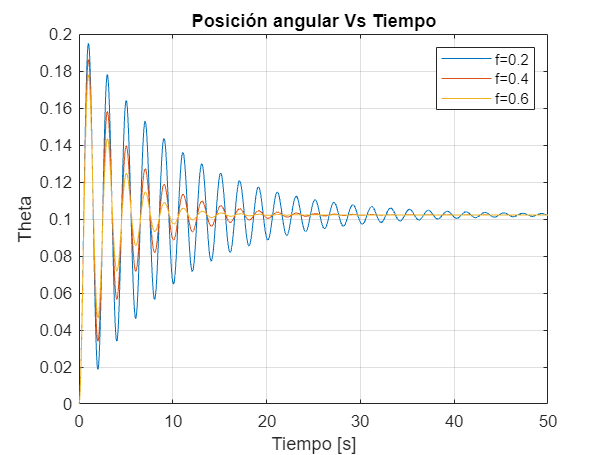

syms x1(t) x2(t)

%DEFINIMOS VARIABLES DE ESTADO
m=1; %masa
g=9.8; %gravedad
l=1; %longitud [m]
fv=[0.2 0.4 0.6]; %factor de fricción
u=1; %Fuerza tangencial

tspan=0:0.01:50;

%CREAMOS CICLO CON SLN Y GRÁFICA DE LA EC PARA CADA f
figure;
for i=1:length(fv)
    f=fv(i);
    f1=x2;
    f2=-(g/l)*sin(x1)-(f/m)*x2+u/(m*l);
    ci = [0 0];
    func=odeFunction([f1 f2], [x1 x2]);
    [~,sol] = ode45(func,tspan,ci);
    theta = sol(:,1);
    omega = sol(:,2);
    plot(tspan,theta)
    title('Posición angular Vs Tiempo')
    xlabel('Tiempo [s]')
    ylabel('Theta')
    hold on
    grid on
end
legend('f=0.2','f=0.4','f=0.6')

Posiblemente la variable más importante es el factor de fricción viscosa. Esto ya que dicho coeficiente define el nivel de oposición que el medio le imprime al sistema. Es por lo anterior que en la gráfica de posición angular respecto al tiempo se puede observar que, a medida que aumenta el coeficiente de fricción, disminuye la amplid del ángulo descrito por las ondas oscilatorias así como el tiempo que le toma al sistema llegar al reposo.

**    PUNTO 8**

Si f = 0, u = 0 (movimiento libre no amortiguado) y la posición angular inicial ω(0) es menor a unos 30° (0.5 radianes, aproximadamente), se puede aproximar el seno del ángulo en radianes por el ángulo (comprobar con la calculadora o MATLAB) y el modelo es lineal. 

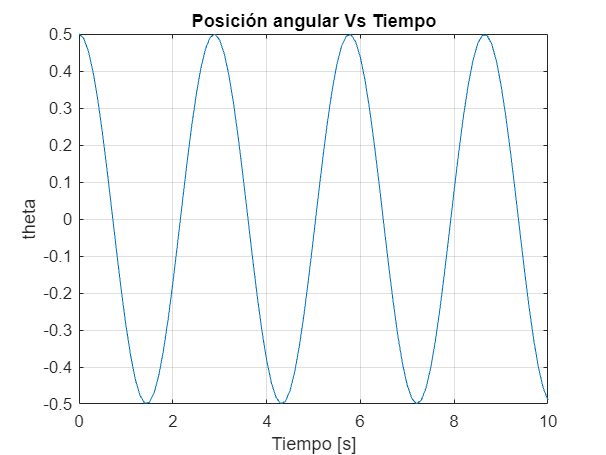

syms x1(t) x2(t)
%DEFINIMOS VARIABLES DE ESTADO
m=1; %masa
g=9.8; %gravedad
l=2; %longitud [m]
f=0; %factor de fricción
u=0; %Fuerza tangencial

%PLANTEAMOS ECUACIONES DIFF
f1=x2;
f2=-(g/l)*sin(x1)-(f/m)*x2+u/(m*l);

%EMPLEAMOS ODEFUNCTION
func=odeFunction([f1 f2], [x1 x2]);
ci=[0.5 0];
tspan=0:0.1:10;
[t,sln]=ode45(func,tspan,ci); 
theta=sln(:,1);
figure;
plot(t,theta)
title('Posición angular Vs Tiempo')
xlabel('Tiempo [s]')
ylabel('theta')
grid on

Como se observa en la gráfica, al eliminar las fuerzas externas del sistema (fuerza tangecial y fuerzas generadas porla fricción viscosa), el sistema se comporta igual que un modelo ideal. Es por lo tanto que se puede observar un movimiento oscilatorio perpetuo pues, dado que solo se tiene la influencia de la masa y la longitud del hilo que sostiene el péndulo, no hay variables que detengan el movimiento a lo largo del tiempo y la gráfica de posición angular en el tiempo describe una función sinusoidal.

- Obtener la ecuación de estado, pasar a la ecuación diferencial homogénea con coeficientes constantes y resolverla analíticamente. ¿Cómo se puede medir la aceleración de la gravedad si se conoce la longitud? ¿Cómo se puede obtener la longitud si se conoce la aceleración de la gravedad? Comprobar los resultados con MATLAB.

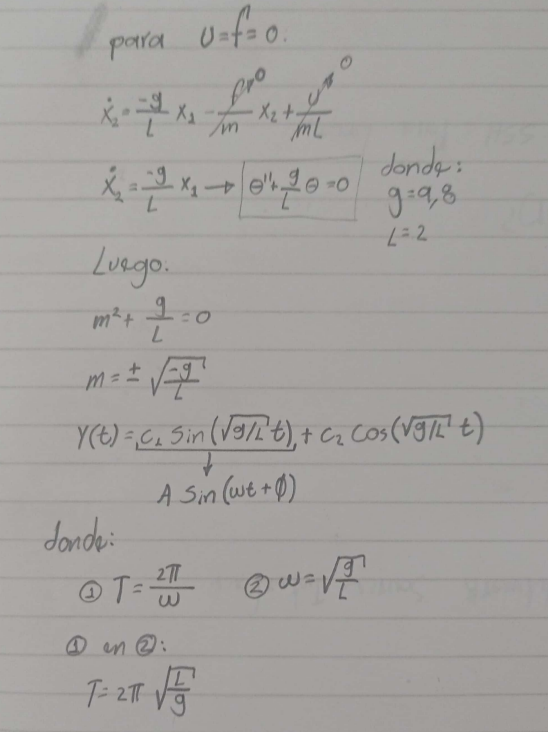

Como se observa en el procedimiento analítico, conociendo el periodo o la frecuencia  de oscilación del sistema, es posible hallar la longitud o la aceleración gravitacional si se tiene una de estas dos ya que se hace posible reemplazar esta información en la fórmula planteada.

**    PUNTO 9**

Si se conoce la respuesta temporal de un péndulo con fuerza igual a 1 N, *l* = 2 y *g* = 9.8, hallar aproximadamente por tanteo los valores de *f* y *m*. Explicar el procedimiento. Tener en cuenta los resultados de las tareas 6 y 7.

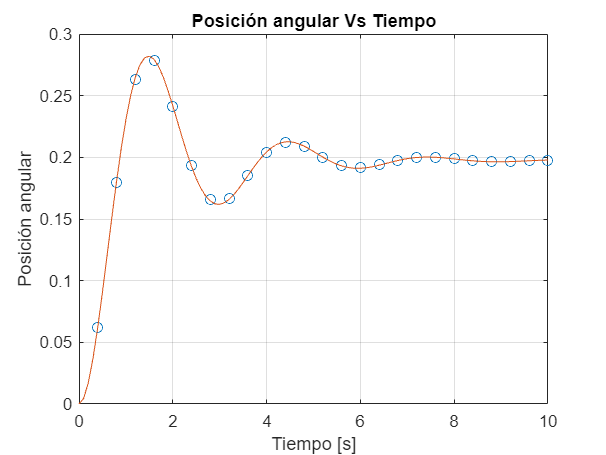

syms x1(t) x2(t)
%DEFINIMOS VARIABLES DE ESTADO
m=0.52; %masa
g=9.8; %gravedad
l=2; %longitud [m]
f=0.6; %factor de fricción
u=1; %Fuerza tangencial

%PLANTEAMOS ECUACIONES DIFF
f1=x2;
f2=-(g/l)*sin(x1)-(f/m)*x2+u/(m*l);

%EMPLEAMOS ODEFUNCTION
func=odeFunction([f1 f2], [x1 x2]);
ci=[0 0];
tspan=0:0.1:10;
[t,sln]=ode45(func,tspan,ci); 
theta=sln(:,1);

%VECTORES DE RESPUESTAS TEMPORALES
tspan2=0.4:0.4:10;
angulo=[0.0621 0.1797 0.2635 0.2783 0.2414 0.1932 0.1656 0.1667 0.1852 0.2038 0.2119 0.2086 0.2002 0.1934 0.1915 0.1938 0.1973 0.1997 0.1999 0.1987 0.1972 0.1965 0.1966 0.1972 0.1978];

figure;
plot(tspan2,angulo,'o',t,theta)
title('Posición angular Vs Tiempo')
xlabel('Tiempo [s]')
ylabel('Posición angular')
grid on

Habiendo analizado cada uno de los efectos de las variables en el sistema, se empiezan a cambiar de forma arbitraria los valores de m y f con el fin de lograr alinear la gráfica del modelo matemático con la de los puntos suministrados. El orden de los puntos sugería una amplitud de onda relativamente alta con respecto a los putnos anteriores con un espacio entre picos considerable así como una estabilización rápida y una disminución de amplitud entre ondas bastante agresiva. Por tanto, se determinó a través de prueba y error que una masa de 0.5 Kg (menor a los puntos anteriores) y un coeficiente de fricción de 0.6 Kg/s permiten que se obtenga un comportamiente de la posición angular a través del tiempo semejante a la descrita por los puntos entregados.

**    PUNTO 10**

Montar un experimento en casa de un péndulo con entrada igual cero y un ángulo inicial entre 20 y 60°, y hallar los parámetros *l* y *f* si se conocen *m* y *g*. Es decir, suponer que no se sabe la longitud. Al final, mostrar la discrepancia de la longitud. ¿Por qué si no hay entrada el experimento no sirve para hallar *f* y *m* como en la tarea anterior?

Se realiza un experimento en el laboratorio de física de la universidad con una masa de 0.52 Kg y un hilo rígido de 0.85 m de longitud.

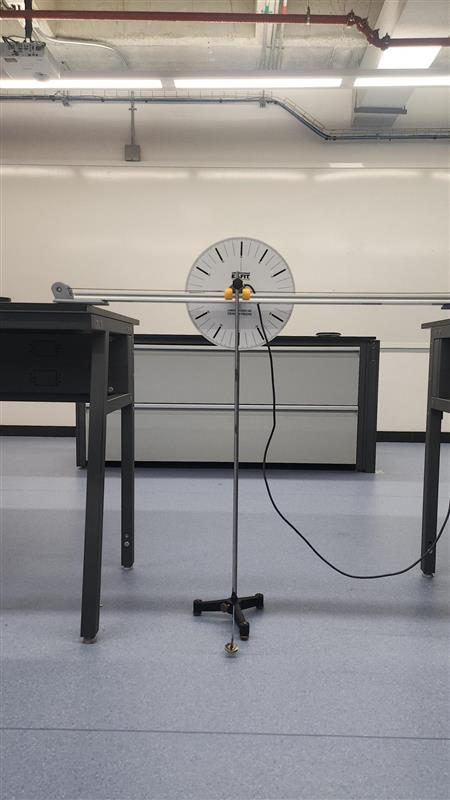

Asimismo, se midio de forma experimental un periodo oscilatorio de 1.8 segundos. Tomando la aceleración gravitacional como 9.8 m/s², se hace el cálculo experimental de la longitud del hilo.

Lt=0.85;
T=1.8;
g=9.8;

Lexp=(g*(T^2))/(4*(pi^2))

Lexp = 0.8043

Error=num2str((Lt-Lexp)/Lt*100);
disp(['Se ubtuvo un error porcentual de: ',Error,'%'])

Se ubtuvo un error porcentual de: 5.3779%


A pesar de que con la formula plaanteada es posible calcular la longitud del hilo de manera experimental con un porcentaje de error aceptable, dado el planteamiento de esta fórmula, no es posible calcular variables como la fuerza tangencial del sistema o el coeficiente de fricción viscosa del medio. Esto hace que el cálculo experimental de estas se complique considerablemente.

    **CONCLUSIONES**

La práctica anterior ha permitido explotar la aplicabilidad de modelos matemáticos construidos con ecuaciones diferenciales a sistemas oscilatorios como los de péndulo simple. No solo se logro resolver este sistema para obtener información de la posición y velocidad angular del sistema en el tiempo, sino que también se pudo comprender la manera en que las variables de estado afectan el comportamiento del sistema, incluyendo variables como la masa, aceleración gravitacional, fuerza tangencial, coeficiente de fricción del ambiente y longitud del hilo.

Se puede concluir entonces que la aplicación de ecuaciones diferenciales son una herramienta sumamente completa que permiten estudiar a detalle fenomenos físicos oscilatorios como los de los sistemas de péndulo simple.